clearvars; close all; % clear variables in workspace and close all figures


% reading the data
data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');

% TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
% data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables % y = (x - min) / (max - min)

tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

% norm / denormalization function 
norm = @(x, Max, Min)((x-Min)/(Max-Min)); % y = (x - min) / (max - min)
denorm = @(y,Max,Min)(y*(Max-Min)+Min);
Min =mindp(1); Max= maxdp(1);

% clearvars -except data ndata mindp maxdp

% Training and Testing Data Split
TR = timerange('2018-01-01','2020-10-20 23:00:00', "closed");
trainvald = ndata(TR, :);   % training data

TR = timerange('2020-10-21','2021-10-20 23:00:00', "closed");
testd = ndata(TR, :);   % testing data 

## The Seasonal Naive Approach

### Predict the test dataset

% Takes the actual demand of the previous week
TR = testd.DateTime - days(7);
yNaive = ndata.DemandMW(TR);

% Denormalization
actuals = testd.DemandMW * (maxdp(1) - mindp(1)) + mindp(1);
yNaive = yNaive * (maxdp(1) - mindp(1)) + mindp(1);

### Calculate errors

[Metrics, errors, AEs, APEs, MAPE] = ErrorMetrics(actuals, yNaive);

Metrics

Metrics = 6×2 table
                   Metrics                      Var2  
    ______________________________________    ________

    {'MAPE - Mean Absolute Percent Error'}      9.3879
    {'ME - Mean Error'                   }    0.075447
    {'MAE - Mean Absolute Error'         }      10.958
    {'MSE - Mean Squared Error'          }      285.76
    {'RMSE - Root Mean Squared Error'    }      16.904
    {'Standard Deviation'                }      16.905


### Plots of the Test dataset

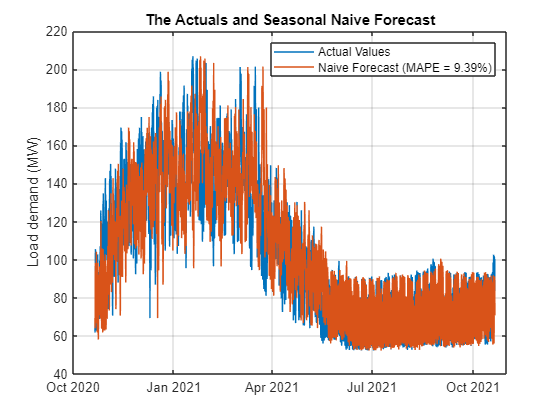

figure;

% plot actual values
plot(testd.DateTime, actuals, 'DisplayName','Actual Values')
title('The Actuals and Seasonal Naive Forecast')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot naive forecast
DisplayName = num2str(MAPE, 'Naive Forecast (MAPE = %.2f%%)');
plot(testd.DateTime, yNaive, 'DisplayName', DisplayName)
legend('show')

[DailyPeak]= PeakDetection(testd.DateTime, actuals, yNaive);
DailyPeak

DailyPeak = 365×7 timetable
       Time        ActPkHr    ActPk     PredPkHr    PredPk    TimeDiff    ValueDiff     APEs  
    ___________    _______    ______    ________    ______    ________    _________    _______

    21-Oct-2020      12       105.53       11         98         -1          -7.53      7.1354
    22-Oct-2020      14       99.352        8        104         -6         4.6479      4.6782
    23-Oct-2020      12        102.8       17         98          5        -4.7983      4.6677
    24-Oct-2020      10       93.475       19         92          9        -1.4748      1.5778
    25-Oct-2020      19       107.11       1

% Overall MAPE
DayPk_MAPE = mean(DailyPeak.APEs)

DayPk_MAPE = 8.3417

% gives you the hours, minutes, seconds
DayPk_TimeDiff_MBE = round(minutes(hours(mean(DailyPeak.TimeDiff)))) 

DayPk_TimeDiff_MBE = -2

DayPk_TimeDiff_MAE = round(minutes(hours(mean(abs(DailyPeak.TimeDiff)))))

DayPk_TimeDiff_MAE = 209

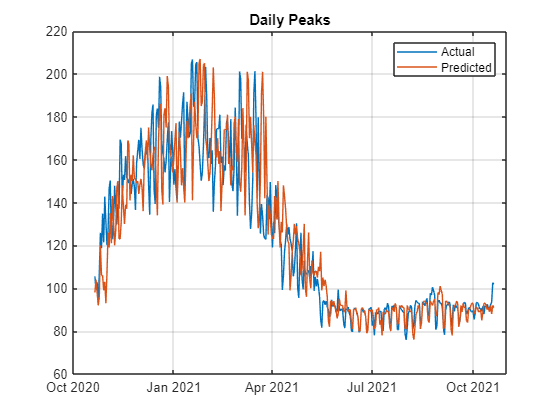

% Plots of the daily peaks
figure;
plot(DailyPeak.Time, DailyPeak.ActPk, 'DisplayName','Actual')
title('Daily Peaks')
hold on
plot(DailyPeak.Time, DailyPeak.PredPk, 'DisplayName', 'Predicted')
grid on
legend('show')